y = {};
for i = 1 : length(uq_efo)
        y{i} = find(efo == uq_efo(i));
end

for j = 1 : length(y)
    num(j) = size(y{j}, 2);
end

loc_idx = [];
idx = find(num > 9);

for k = 1 : length(idx)
    for l = 1 : length(y{idx(k)})
    temp = y{idx(k)};
    loc_idx = [loc_idx; temp(l)]; 
    end
end

loc1 = loc(loc_idx, 1:3) 

loc1 = 	1.0e+-5 *

    0.1177   -0.2128    0.0027
   -0.2690   -0.0417   -0.0039
   -0.2647   -0.0309   -0.0028
    0.2944   -0.1596    0.0048
    0.0690   -0.1127   -0.0036
    0.0001   -0.0405    0.0018
   -0.0003   -0.0394    0.0023
    0.0025   -0.0399    0.0103
   -0.0005   -0.0372    0.0008
    0.0016   -0.0359    0.0046


efo1 = efo(loc_idx')

efo1 = 	1.0e+06 *

    0.0675    0.0675    0.0675    0.0675    0.0675    0.0675    0.0675    0.0675    0.0675    0.0675    0.0695    0.0695    0.0695    0.0695    0.0695    0.0695    0.0695    0.0695    0.0695    0.0695    0.0695    0.0820    0.0820    0.0820    0.0820    0.0820    0.0820    0.0820    0.0820    0.0820    0.0820    0.0820    0.0880    0.0880    0.0880    0.0880    0.0880    0.0880    0.0880    0.0880    0.0880    0.0880    0.0905    0.0905    0.0905    0.0905    0.0905    0.0905    0.0905    0.0905


k = 1;
for i = 1 : length(cluster)
    if i ~= length(cluster)
        for j = 1 : length(cluster{i})
            loc_nonoise(k, 1:3) = loc(cluster{i}(j), :);
            dcr_nonoise(k) = dcr(cluster{i}(j));
            k = k + 1;
        end
    end
end

k = 1;
for i = 1 : length(fbg)
    if fbg(i) < 0.8
        loc1(k, :) = loc(i, 1:3);
        dcr1(k) = loc(i);
        k = k + 1;
    end
end

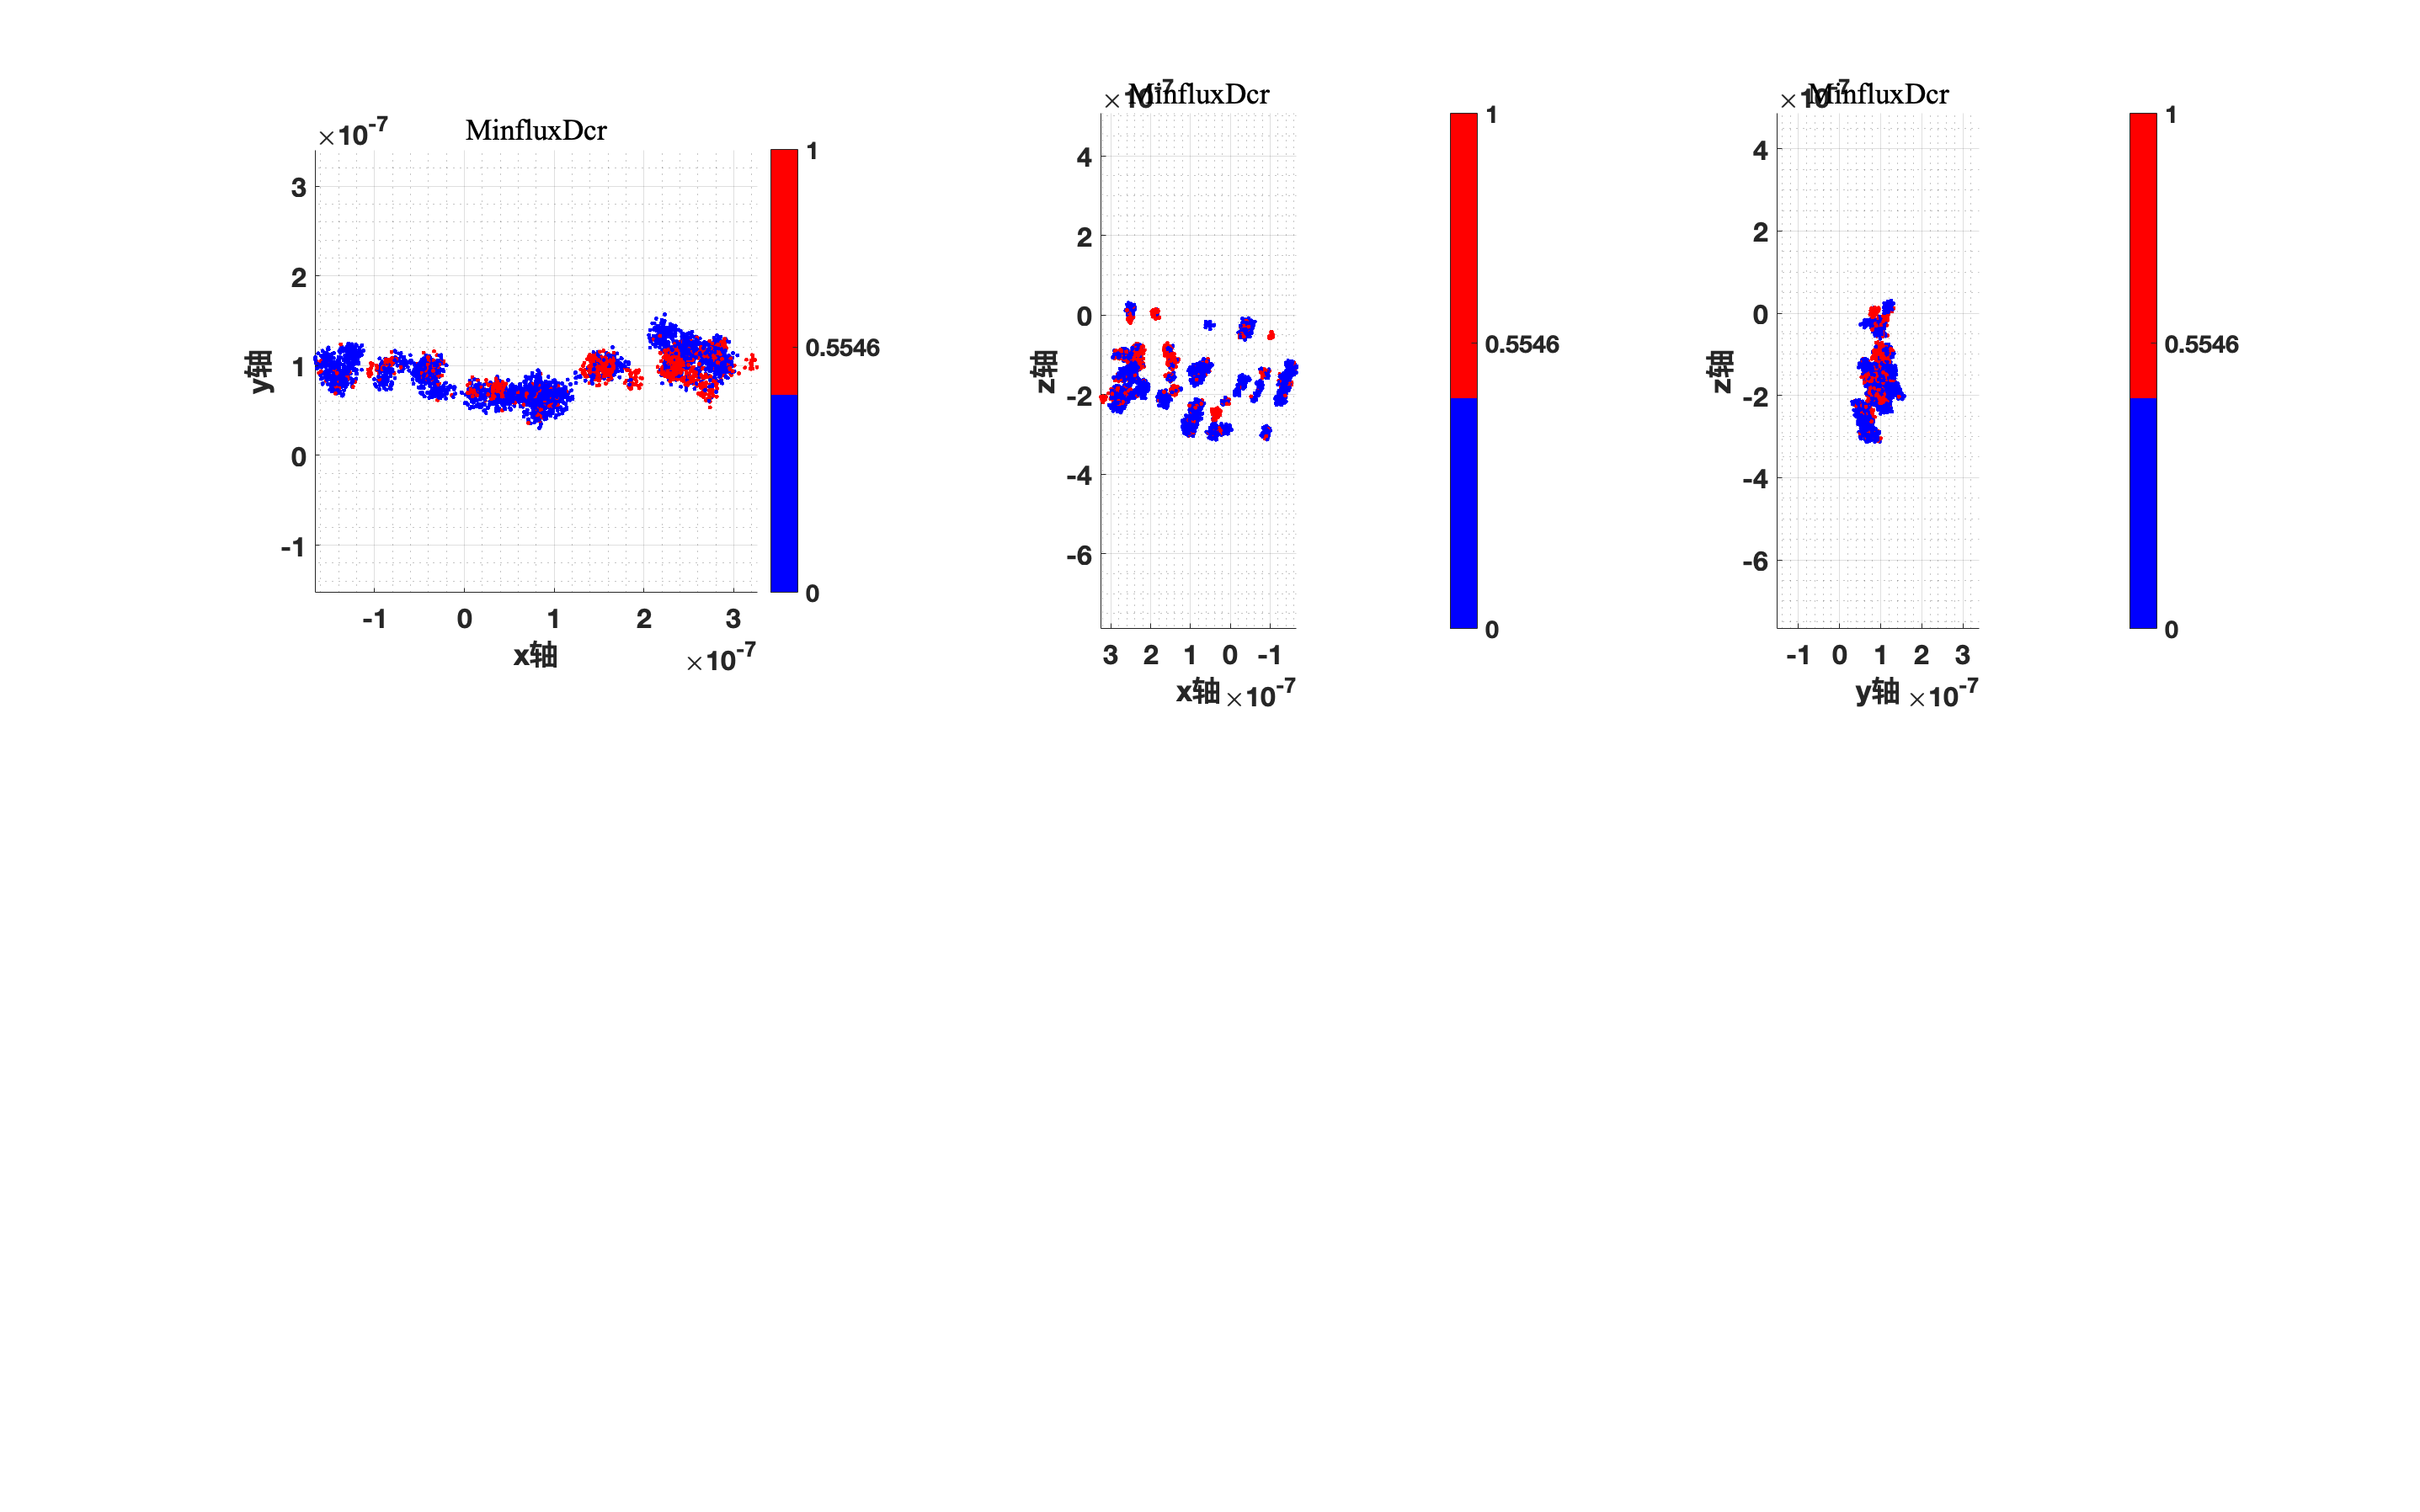

threshold = evalpts_min(find(kernel_min == min(kernel_min)));

if flag3 == true
    loc = loc_aim;
    dcr = dcr_aim;
end

loc = loc_nonoise;
i = find(dcr >= threshold);
loc1 = loc(i, :);
j = find(dcr < threshold);
loc2 = loc(j, :);

if ~isempty(loc1) && ~isempty(loc2)
    l1 = floor(256*threshold);
    l2 = floor(256*(1-threshold));
    bar1 = [linspace(0,0,l2)', linspace(0,0,l2)', linspace(1,1,l2)'];
    bar2 = [linspace(1,1,l1)', linspace(0,0,l1)', linspace(0,0,l1)'];
    colormap(cat(1, bar1, bar2))
else
    colormap([1, 0, 0])
end


subplot(2,3,1)
if size(loc, 2) == 3
    scatter3(loc1(:, 1), loc1(:, 2), loc1(:, 3), 'b.');
    hold on;
    scatter3(loc2(:, 1), loc2(:, 2), loc2(:, 3), 'r.');
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'zgrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    set(gca, 'zminorgrid', 'on');
    title('MinfluxDcr', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    hold off;
end
view([0, 0, 1])
axis equal
colorbar('Ticks',[0, threshold, 1]);

scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);

subplot(2,3,2)
if size(loc, 2) == 3
    scatter3(loc1(:, 1), loc1(:, 2), loc1(:, 3), 'b.');
    hold on;
    scatter3(loc2(:, 1), loc2(:, 2), loc2(:, 3), 'r.');
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'zgrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    set(gca, 'zminorgrid', 'on');
    title('MinfluxDcr', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    hold off;
end

view([0, 1, 0])
axis equal
colorbar('Ticks',[0, threshold, 1]);

scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);

subplot(2,3,3)
if size(loc, 2) == 3
    scatter3(loc1(:, 1), loc1(:, 2), loc1(:, 3), 'b.');
    hold on;
    scatter3(loc2(:, 1), loc2(:, 2), loc2(:, 3), 'r.');
    xlabel('x轴')
    ylabel('y轴')
    zlabel('z轴')
    set(gca, 'xgrid', 'on');
    set(gca, 'ygrid', 'on');
    set(gca, 'zgrid', 'on');
    set(gca, 'xminorgrid', 'on');
    set(gca, 'yminorgrid', 'on');
    set(gca, 'zminorgrid', 'on');
    title('MinfluxDcr', 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 16, 'FontWeight', 'bold');
    hold off;
end
view([1, 0, 0])
axis equal
colorbar('Ticks',[0, threshold, 1]);

scrsz = get(0, 'ScreenSize');
set(gcf, 'Position', scrsz);
